### Choose chromosome

% note this only works for chromosomes 1 and 2
chromosome_of_interest = 'chr1';

### Choose transcription factor

can search for common TFs in [find_popular_TF.mlx](find_popular_TF.mlx_)

TF_of_interest = 'CTCF';

## Read sequence

tic

filename = strcat("Human Genome/", chromosome_of_interest, "_shorter.txt")

filename = "Human Genome/chr1_shorter.txt"

f = fopen(filename,'rt');
chrm_sequence = fgetl(f);
toc

Elapsed time is 8.770343 seconds.


L = length(chrm_sequence)

L = 12000000

fclose(f);

chrm_sequence = string(chrm_sequence)

chrm_sequence = "NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN

### Get the PWM for chosen TF

[pwm_matrix, TF_binding_length] = getPWM(TF_of_interest);

pwmatrix =     0.0550    0.0250    0.0690    0.0430    0.0010    0.2630    0.0050    0.0010    0.0330    0.2670    0.0210    0.0810    0.0110    0.0270    0.1270
    0.3190    0.6470    0.0430    0.7910    0.9950    0.6670    0.6190    0.9990    0.0650    0.0910    0.3450    0.1950    0.0030    0.0670    0.5950
    0.5670    0.0250    0.7930    0.0630    0.0010    0.0470    0.0030    0.0030    0.0090    0.5650    0.6210    0.0450    0.9770    0.8410    0.0750
    0.0630    0.3070    0.0990    0.1070    0.0070    0.0270    0.3770    0.0010    0.8970    0.0810    0.0170    0.6830    0.0130    0.0690    0.2070


pwmatrix =    -2.9004   -3.6889   -2.6736   -3.1466   -6.9078   -1.3356   -5.2983   -6.9078   -3.4112   -1.3205   -3.8632   -2.5133   -4.5099   -3.6119   -2.0636
   -1.1426   -0.4354   -3.1466   -0.2345   -0.0050   -0.4050   -0.4797   -0.0010   -2.7334   -2.3969   -1.0642   -1.6348   -5.8091   -2.7031   -0.5192
   -0.5674   -3.6889   -0.2319   -2.7646   -6.9078   -3.0576   -5.8091   -5.8091   -4.7105   -0.5709   -0.4764   -3.1011   -0.0233   -0.1732   -2.5903
   -2.7646   -1.1809   -2.3126   -2.2349   -4.9618   -3.6119   -0.9755   -6.9078   -0.1087   -2.5133   -4.0745   -0.3813   -4.3428   -2.6736   -1.5750


## Get TF Binding Positions if not already saved

load_name = strcat(TF_of_interest, '_', chromosome_of_interest,  '_binding_positions')

load_name = 'CTCF_chr1_binding_positions'

load(load_name, "TF_binding_pos")

### Create New Positions If not Saved

stop_searching = 487;
if chromosome_of_interest == 'chr1'
    stop_searching = 487
elseif chromosome_of_interest == 'chr2'
    stop_searching = 240
end

stop_searching = 487

% TF_binding_pos = get_TF_binding_pos(chromosome_of_interest,TF_of_interest, stop_searching)

### Overwrite positions

% save_name = strcat(TF_of_interest, '_', chromosome_of_interest,  '_binding_positions')

save_name = 'CTCF_chr2_binding_positions'

% save(save_name, "TF_binding_pos")

## Create Start codon matrix

[counts, num_TFs] = get_start_matrix(TF_of_interest);

histogram(counts)

start_matrix = counts / num_TFs;
start_matrix = log(start_matrix + 0.0001);

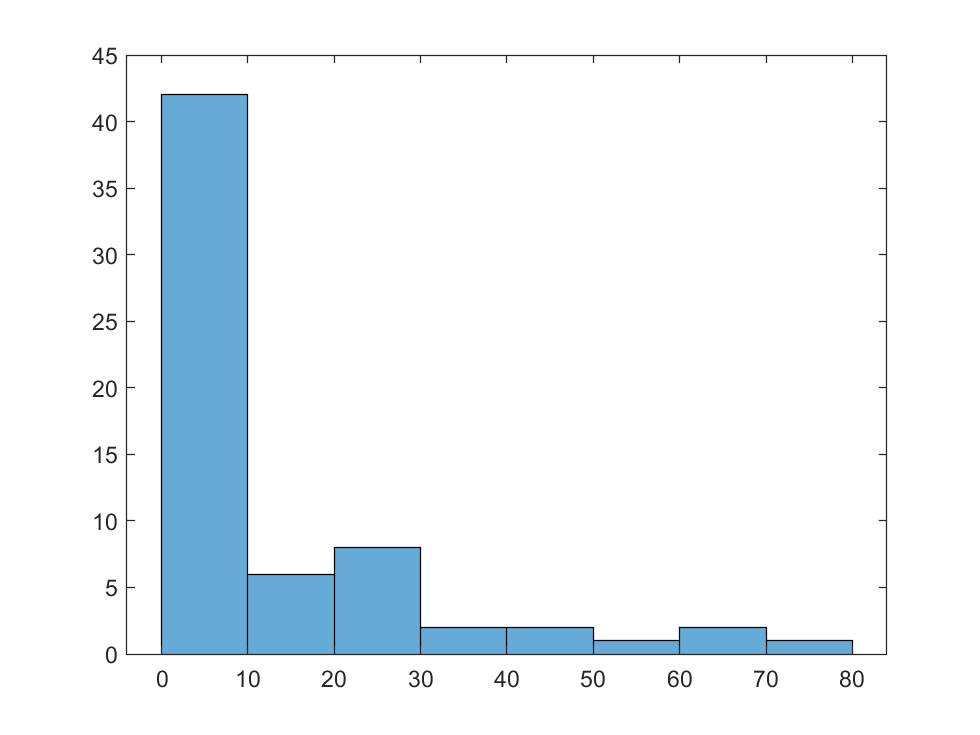


counts = zeros(64, 1);
load("codons")

for i=1:length(TF_binding_pos)
% for i=1:10
    site_id_num = TF_binding_pos(i, 1);
    start1 = TF_binding_pos(i, 2);
    strand = TF_binding_pos(i, 3);
    
    if strand == 1
        start_codon = extractBetween(chrm_sequence,start1+1,start1+3);
        pos = find(codons == start_codon);
        counts(pos, 1) = counts(pos, 1) + 1;
    else 
        start_codon = extractBetween(chrm_sequence,start1+TF_binding_length-2,start1+TF_binding_length);
        start_codon = reverse(start_codon);
        pos = find(codons == start_codon);
        counts(pos, 1) = counts(pos, 1) + 1;
    end

end
start_matrix = counts / length(TF_binding_pos);
start_matrix = log(start_matrix + 0.0001);
histogram(counts)

## Get Actual Positions

actual_positions = [];

## Calculate My Own TWM to confirm accuracy of positions

nukes = {'A', 'C', 'G', 'T'};
my_own_TWM_row = repmat([0], 1, TF_binding_length);
my_own_TWM = repmat(my_own_TWM_row, 4, 1)

my_own_TWM =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## Calculate Minimum Score of a binding region for a particular TF.

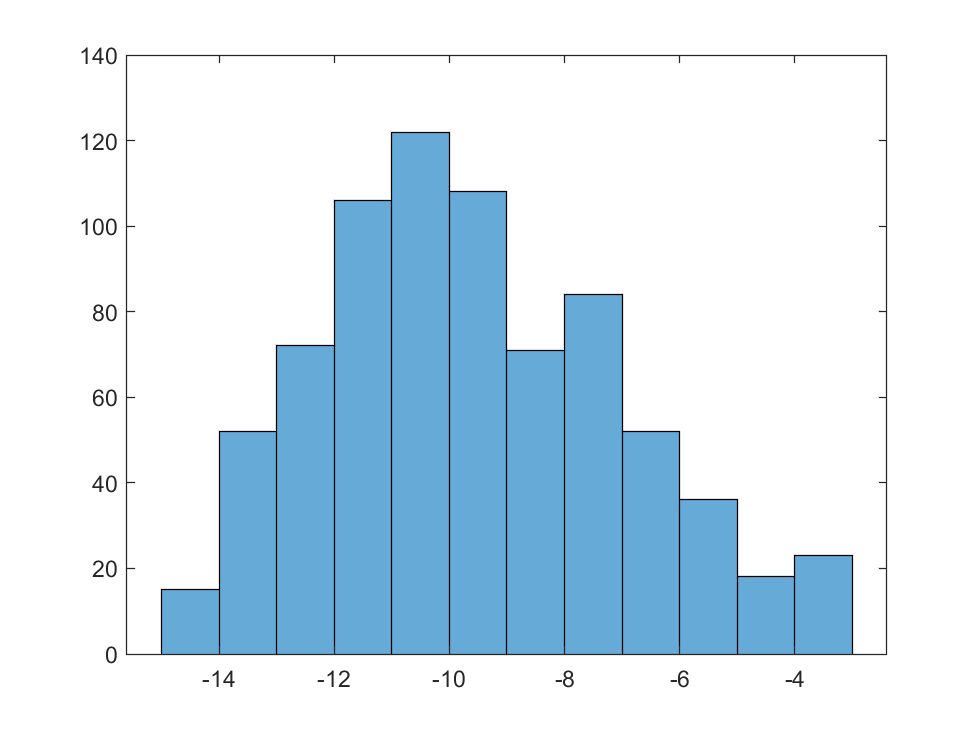

h =   Histogram with properties:

             Data: [759×1 double]
           Values: [15 52 72 106 122 108 71 84 52 36 18 23]
          NumBins: 12
         BinEdges: [-15 -14 -13 -12 -11 -10 -9 -8 -7 -6 -5 -4 -3]
         BinWidth: 1
        BinLimits: [-15 -3]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


scores = [];

for i=1:length(TF_binding_pos)
% for i=1:10
    site_id_num = TF_binding_pos(i, 1);
    start1 = TF_binding_pos(i, 2);
    strand = TF_binding_pos(i, 3);
    
    if strand == 1
        for k = 1:TF_binding_length
            r = extractBetween(chrm_sequence,start1+k,start1+k);
            pos = find(nukes == r);
            my_own_TWM(pos, k) = my_own_TWM(pos, k) + 1;
        end
        r = extractBetween(chrm_sequence,start1+1,start1+TF_binding_length);
        score =  get_score(0, r, pwm_matrix, TF_binding_length, 1, start_matrix, codons);
        scores = [scores; score];
        actual_positions = [actual_positions; site_id_num, start1+1, 1, ceil(score)];
    else 
        for k = 1:TF_binding_length
            r = extractBetween(chrm_sequence,start1+k,start1+k);
            pos = find(nukes == r);
            my_own_TWM(5-pos, TF_binding_length-k+1) = my_own_TWM(5-pos, TF_binding_length-k+1) + 1;
        end
        r = extractBetween(chrm_sequence,start1+1,start1+TF_binding_length);
        score = get_score(0, r, pwm_matrix, TF_binding_length, 0, start_matrix, codons);
        scores = [scores; score];
        actual_positions = [actual_positions; site_id_num, start1+1, 0, ceil(score)];
    end

end
h = histogram(scores)

min(scores)

ans = -14.4154

mean(scores)

ans = -9.5940

std(scores)

ans = 2.5680

mean(scores) - std(scores)

ans = -12.1620

my_own_TWM = my_own_TWM / length(actual_positions)

my_own_TWM =     0.0632    0.0527    0.0856    0.0567         0    0.2490    0.0053         0    0.1094    0.1449    0.0224    0.1383    0.0211    0.0250    0.0909
    0.4216    0.6179    0.0962    0.7615    0.9829    0.5876    0.6970    0.9881    0.1607    0.1805    0.4730    0.2688    0.0105    0.1779    0.6140
    0.4717    0.0751    0.6588    0.1304         0    0.0856    0.0158    0.0119    0.0369    0.5784    0.4796    0.1120    0.9394    0.7299    0.1489
    0.0435    0.2543    0.1594    0.0514    0.0171    0.0777    0.2819         0    0.6930    0.0962    0.0250    0.4809    0.0290    0.0672    0.1462


exp(pwm_matrix) - 0.01

ans =     0.0450    0.0150    0.0590    0.0330   -0.0090    0.2530   -0.0050   -0.0090    0.0230    0.2570    0.0110    0.0710    0.0010    0.0170    0.1170
    0.3090    0.6370    0.0330    0.7810    0.9850    0.6570    0.6090    0.9890    0.0550    0.0810    0.3350    0.1850   -0.0070    0.0570    0.5850
    0.5570    0.0150    0.7830    0.0530   -0.0090    0.0370   -0.0070   -0.0070   -0.0010    0.5550    0.6110    0.0350    0.9670    0.8310    0.0650
    0.0530    0.2970    0.0890    0.0970   -0.0030    0.0170    0.3670   -0.0090    0.8870    0.0710    0.0070    0.6730    0.0030    0.0590    0.1970


dif = my_own_TWM - (exp(pwm_matrix) - 0.01);
mean(mean(dif))

ans = 0.0090

actual_positions

actual_positions =            1      237750           1         -10
           1      237752           0          -7
           1      237762           0          -9
           2      521533           1         -10
           2      521535           0          -6
           2      521545           0          -9
           3      714183           1         -11
           3      714273           0          -8
           5      805272           1          -9
           5      805298           1         -10


## Predict Positions for PWM

threshold = min(scores)

threshold = -14.4154

positions = predict_positions(chrm_sequence, chromosome_of_interest, pwm_matrix, TF_binding_length, threshold, stop_searching, start_matrix, codons)

positions =            1      237596           1         -14
           1      237750           1         -10
           1      237752           0          -7
           1      237762           0          -9
           2      521379           1         -14
           2      521533           1         -10
           2      521535           0          -6
           2      521545           0          -9
           3      713887           1         -14
           3      713890           1         -14


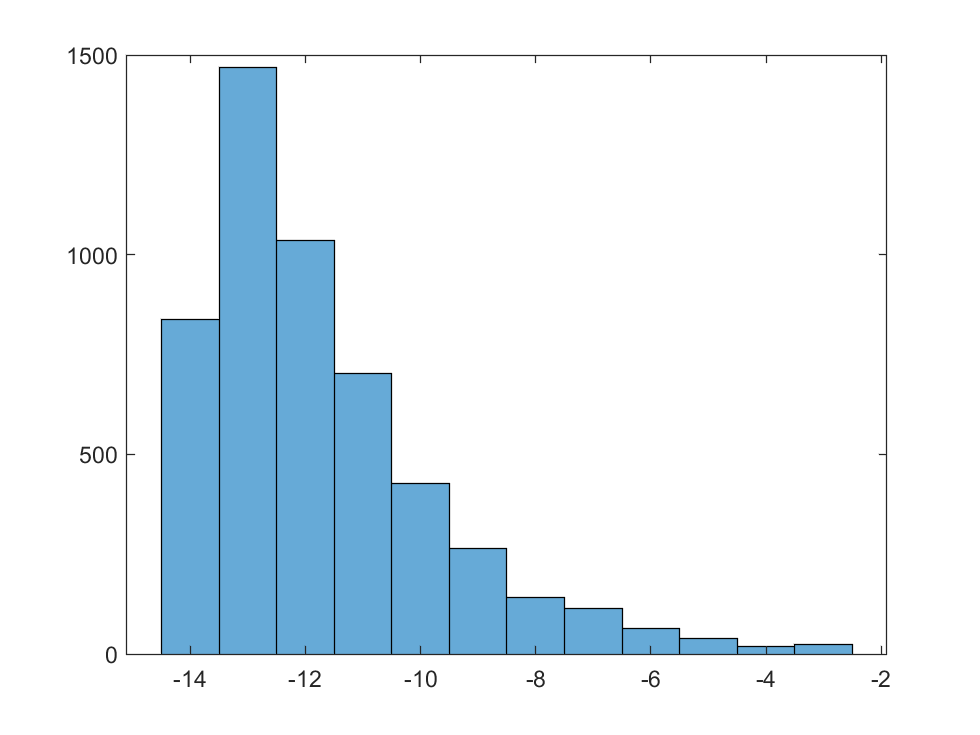

histogram(positions(:, 4))

## Compare scores of found vs not found

[found,found_scores, not_found_scores] = check_found(chrm_sequence, positions,actual_positions, pwm_matrix, TF_binding_length, start_matrix, codons);

mean(found_scores)

ans = -9.5940

std(found_scores)

ans = 2.5680

mean(not_found_scores)

ans = NaN

found

found = 759

percentageFound = found / length(actual_positions)

percentageFound = 1

found / length(positions(:, 1))

ans = 0.1477

## Positive vs negative

positive = 0;
success = false;
positive_scores = [];
negative_scores = [];

merged_data = [];

for k=1:length(positions)
    for i=1:length(actual_positions)
        if positions(k,2) == actual_positions(i, 2) && positions(k, 3) == actual_positions(i, 3)
            positive = positive + 1;
            region = extractBetween(chrm_sequence,actual_positions(i, 2),actual_positions(i, 2) + TF_binding_length + 1);
            score = get_score(0, region, pwm_matrix, TF_binding_length, actual_positions(i, 3));
            merged_data = [merged_data; actual_positions(i, :) 1];
            positive_scores = [positive_scores; ceil(score)];
            success= true;
            break; 
        end
    end
    if success == false
        false;
        region = extractBetween(chrm_sequence,positions(k, 2),positions(k, 2) + TF_binding_length + 1);
        score = get_score(0, region, pwm_matrix, TF_binding_length, positions(k, 3));
        negative_scores = [negative_scores; ceil(score)];
        merged_data = [merged_data; positions(k, :) 0];
    end
    success = false;
end

Not enough input arguments.

Error in get_score (line 12)
        pos = find(codons == start_codon);


mean(positive_scores)
std(positive_scores)
mean(positive_scores) - std(positive_scores)
mean(negative_scores)
std(negative_scores)
mean(negative_scores) - std(negative_scores)
positive
percentagePositive = positive / length(positions)
positive / length(actual_positions(:, 1))
merged_data

## Save Data

save_name = strcat(TF_of_interest, '_',  chromosome_of_interest, '_positions')

save_name = 'CTCF_chr2_positions'

save(save_name, "merged_data")